%% for hmatrix 9x12 use the following code 

%reading from the Hmatrix9x12 text file:
%{
mat = fileread('Hmatrix9x12.txt');
mat = strtrim(mat);
rows = strsplit(mat, '\n');
h_mat = zeros(length(rows), length(strsplit(rows{1},' ')));

for i = 1:length(rows)
    values = strsplit(rows{i}, ' ');
    for j = 1:length(values)
        h_mat(i, j) = str2double(values{j});
    end
end
%}

%% for HMatrix.mat and HMatrix2.mat use this code:
data=load('Hmatrix2.mat');
h_mat=data.H;

COL = length(h_mat(1,:));
ROW = length(h_mat(:,1));

deg_CN = 0; % Degree of Cn
deg_VN = 0; % Degree of Vn

%Calculating Degree of CNs(no. of 1's in a row) and VNs(no. of 1's in a column)

for i = 1:COL
    if h_mat(1,i) == 1
    deg_CN = deg_CN + 1;
    end
end

for j = 1:ROW
    if h_mat(j,1) == 1
    deg_VN = deg_VN + 1;
    end
end

% storing the indexes of the VNs connected to a particular CN
VNs_conn_to_CN = -1*ones(ROW, deg_CN); 

%storing the indexes of the CNs connected to a particular VN
CNs_conn_to_VN = -1*ones(COL, deg_VN); 

% filling VNs_conn_to_CN
for i = 1:ROW
    k = 1;
    for j = 1:COL %keeping the row constant(CN) and iterating over columns(VNs) to check for the 1's in a single row
        if h_mat(i,j) == 1
            VNs_conn_to_CN(i,k) = j;
            k = k + 1;
        end
    end
end

%  filling CNs_conn_to_VN
for i = 1:COL
    k = 1;
    for j = 1:ROW % keeping the column constant(VN) and iterating over rows(CNs) to check for the 1's in a single column
        if h_mat(j,i) == 1
            CNs_conn_to_VN(i,k) = j;
            k = k + 1;
        end
    end
end

p = 0;
P_succ = [];
Nsim=100;
iter = 1:1:50;
num_iter = size(iter);
deltap=0.1;
Prob = 0:deltap:1;

fprintf('\nHMatrix with Rows: %d and Columns: %d', ROW, COL);


HMatrix with Rows: 3000 and Columns: 5000

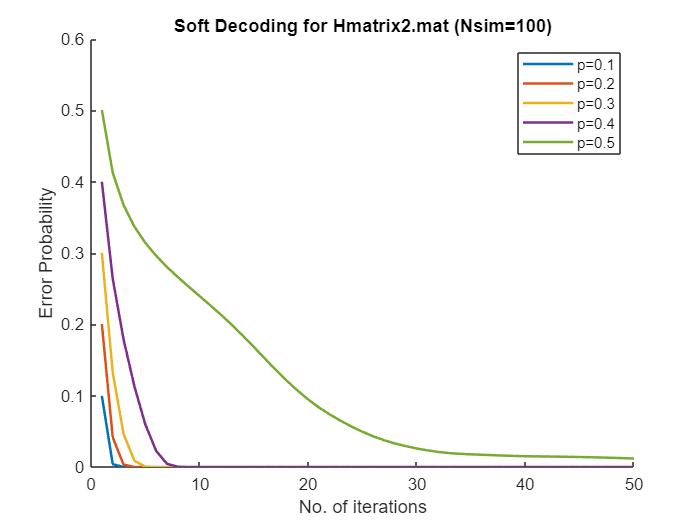

%fprintf('\nBEC(p)\tProbability of Success(LDPC)\n');

while p<1.01
    No_of_err = 0;
    overall_err = zeros(num_iter);
    for Sim = 1:Nsim
        msg_from_bec = zeros(1, COL);
        pr_from_CN_to_VNs = -ones(ROW, COL); % For storing message that each cN will sent to vN (Probability)
        pr_from_VN_to_CNs = -ones(ROW, COL); % For storing message that each vN will sent to cN (Probability)
        decoded_msg = zeros(1, COL);

        %noise introduced by the BEC channel with probability p
                for i = 1:length(msg_from_bec)
                    % Generate a random number between 0 and 1
                    r = rand();
                    if r <= p
                        msg_from_bec(i) = -1; %erasure bit introduced
                    end
                end

        decoded_msg = msg_from_bec;

        %Loading the VNs with the msg received from BSC channel that will be sent to CNs
        for g = 1:length(msg_from_bec) 
            if msg_from_bec(g) == 1
                pr_from_VN_to_CNs(:, g) = ones(ROW, 1);
            elseif msg_from_bec(g) == 0
                pr_from_VN_to_CNs(:, g) = zeros(ROW, 1);
            elseif msg_from_bec(g) == -1
                pr_from_VN_to_CNs(:, g) = 0.5 * ones(ROW, 1);
            end
        end

        %  iterations will stop if it_ind=100 or we receive the original msg of all 0's which is checked by the function 'check' 
        it_ind = 1;
        err_in_each_iter = zeros(num_iter);
        while it_ind <= num_iter(2) && ~check_all_zero(decoded_msg)
            err_in_each_iter(it_ind) = count_error(decoded_msg);
            % Sending the msg from CNs to connected VNs
            for i = 1:ROW
                for t = 1:deg_CN 
                    pr_from_CN_to_VNs(i, VNs_conn_to_CN(i, t)) = SPC_decoding(VNs_conn_to_CN(i, t), VNs_conn_to_CN, pr_from_VN_to_CNs, i, deg_CN);
                end
            end

             % Sending the msg from VNs to connected CNs
            for l = 1:COL
                % pr = 1 (if r_i = 1) , 0 (if r_i = 0) and 0.5 (if r_i = -1 erasure)
                if msg_from_bec(l) == 1
                    pr = 1;
                elseif msg_from_bec(l) == 0
                    pr = 0;
                elseif msg_from_bec(l) == -1
                    pr = 0.5;
                end

                for t = 1:deg_VN 
                    pr_from_VN_to_CNs(CNs_conn_to_VN(l, t), l) = Majority_decoding(pr, CNs_conn_to_VN(l, t), CNs_conn_to_VN, pr_from_CN_to_VNs, l, deg_VN);
                end
                %fixing the value of the VNs after one complete msg passing from CN to VN and VN to CN
                decoded_msg(l) = Majority_decoding(pr, -1, CNs_conn_to_VN, pr_from_CN_to_VNs, l, deg_VN);
            end
           
            it_ind = it_ind + 1;
        end
        overall_err = overall_err + err_in_each_iter;

        if ~check_all_zero(decoded_msg)
            No_of_err = No_of_err + 1;
        end
    end

    overall_err = overall_err./(COL*Nsim);

    hold on
    %eps is used because some times there are floating point error which
    %does not give the p value as 0.1 or 0.2 exactly.
    if (abs(p-0.1) < eps || abs(p - 0.2) < eps || abs(p - 0.3) < eps || abs(p - 0.4) < eps || abs(p - 0.5) < eps)
        plot(iter,overall_err,LineWidth=1.5);
    end

    P_succ(end+1) = 1 - No_of_err / Nsim;

    %fprintf('\n%.2f\t\t\t%.4f\n', p, P_succ(end));
    p = p + deltap;
end
ylabel('Error Probability');
xlabel('No. of iterations');
title('Soft Decoding for Hmatrix2.mat (Nsim=100)')
legend('p=0.1','p=0.2','p=0.3','p=0.4','p=0.5');

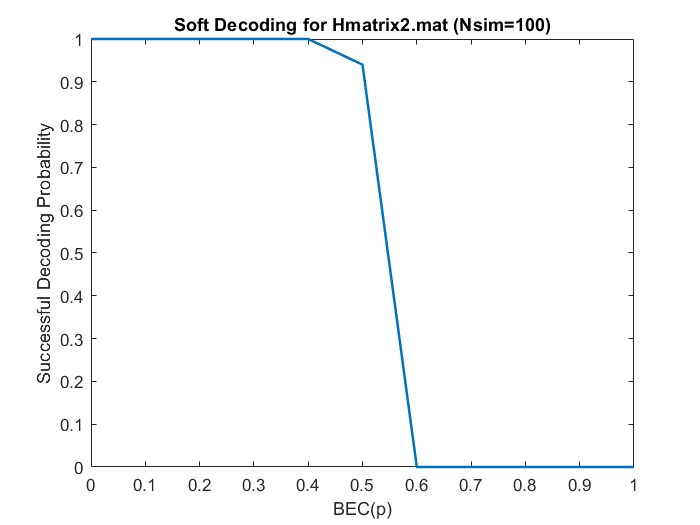

figure
plot(Prob,P_succ,LineWidth=1.5);
ylabel('Successful Decoding Probability');
xlabel('BEC(p)');
title('Soft Decoding for Hmatrix2.mat (Nsim=100)')

function result = SPC_decoding(vn, VNs_conn_to_CN, pr_from_VN_to_CNs, ind, deg_CN)
    result = 0.5;
    for i = 1:deg_CN
        if (VNs_conn_to_CN(ind, i) == vn) %ignore the same vn
            continue;
        else
            result = result * (1 - (2 * pr_from_VN_to_CNs(ind, VNs_conn_to_CN(ind, i))));
        end
    end
    result = 0.5 - result;
end

function res = Majority_decoding(pr, cn, CNs_conn_to_VN, pr_from_CN_to_VNs, ind, deg_VN)
    p1 = pr;
    p0 = 1 - pr;
    
    for i = 1:deg_VN
        if (CNs_conn_to_VN(ind, i) == cn) %ignore the same cn
            continue;
        else
            p1 = p1 * pr_from_CN_to_VNs(CNs_conn_to_VN(ind, i), ind);
            p0 = p0 * (1 - pr_from_CN_to_VNs(CNs_conn_to_VN(ind, i), ind));
        end
    end
    
    d = 1 / (p0 + p1);
    
    if (cn == -1)
        if (p1 / p0 > 1)
            res = 1;
        elseif (p1 / p0 == 1)
            res = -1;
        else
            res = 0;
        end
    else
        res = d * p1;
    end
end

function result = check_all_zero(msg)
    result = all(msg == 0);
end

function cnt = count_error(msg)
    cnt = 0;
    for i = 1:length(msg)
        if msg(i) == -1
            cnt = cnt + 1;
        end
    end
end